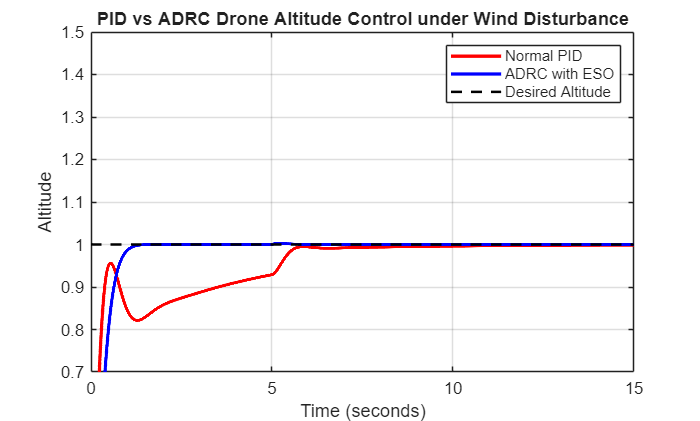

clc;
clear;
close all;

%% Time
dt = 0.001;
t = 0:dt:15;
N = length(t);

%% Desired altitude
r = ones(1,N);

%% Wind disturbance at 5 seconds
d = zeros(1,N);
d(t >= 5) = 1.2;

%% ================= NORMAL PID =================

% PID gains
Kp_pid = 18;
Ki_pid = 5;
Kd_pid = 4;

% Variables
y_pid = zeros(1,N);
ydot_pid = zeros(1,N);

int_pid = 0;
prev_error_pid = 0;

%% ================= ADRC + ESO =================

% ADRC controller gains
kp_adrc = 60;
kd_adrc = 18;

% ESO gains
wo = 35;

beta1 = 3*wo;
beta2 = 3*(wo^2);
beta3 = wo^3;

% ESO states
z1 = 0;   % estimated altitude
z2 = 0;   % estimated velocity
z3 = 0;   % estimated disturbance

b0 = 0.5;

% Variables
y_adrc = zeros(1,N);
ydot_adrc = zeros(1,N);

dist_est = zeros(1,N);

%% ================= SIMULATION =================

for i = 2:N

    %% ---------- NORMAL PID ----------

    error_pid = r(i) - y_pid(i-1);

    int_pid = int_pid + error_pid*dt;

    der_pid = (error_pid - prev_error_pid)/dt;

    u_pid = Kp_pid*error_pid + ...
            Ki_pid*int_pid + ...
            Kd_pid*der_pid;

    % Drone dynamics
    % y'' + 2y' + 5y = u + d

    yddot_pid = u_pid + ...
                d(i) - ...
                2*ydot_pid(i-1) - ...
                5*y_pid(i-1);

    ydot_pid(i) = ydot_pid(i-1) + yddot_pid*dt;

    y_pid(i) = y_pid(i-1) + ydot_pid(i)*dt;

    prev_error_pid = error_pid;


    %% ---------- ADRC + ESO ----------

    % ESO error
    e = z1 - y_adrc(i-1);

    % ADRC control law
    v = kp_adrc*(r(i) - z1) - kd_adrc*z2;

    % disturbance compensation
    u_adrc = (v - z3)/b0;

    % Drone dynamics
    yddot_adrc = u_adrc + ...
                 d(i) - ...
                 2*ydot_adrc(i-1) - ...
                 5*y_adrc(i-1);

    ydot_adrc(i) = ydot_adrc(i-1) + yddot_adrc*dt;

    y_adrc(i) = y_adrc(i-1) + ydot_adrc(i)*dt;

    % ESO update
    z1_dot = z2 - beta1*e;

    z2_dot = z3 + ...
              b0*u_adrc - ...
              beta2*e;

    z3_dot = -beta3*e;

    z1 = z1 + z1_dot*dt;
    z2 = z2 + z2_dot*dt;
    z3 = z3 + z3_dot*dt;

    dist_est(i) = z3;
end

%% ================= PLOT 1 =================
% PID vs ADRC comparison

figure;

plot(t, y_pid, 'r', 'LineWidth', 2);
hold on;

plot(t, y_adrc, 'b', 'LineWidth', 2);

plot(t, r, '--k', 'LineWidth', 1.5);

grid on;

xlabel('Time (seconds)');
ylabel('Altitude');

title('PID vs ADRC Drone Altitude Control under Wind Disturbance');

legend('Normal PID', ...
       'ADRC with ESO', ...
       'Desired Altitude');

ylim([0.7 1.5]);

saveas(gcf,'pid_vs_adrc_comparison.png');

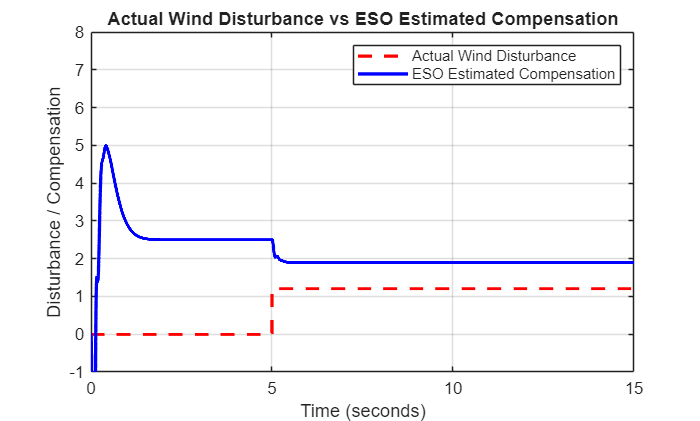


%% ================= PLOT 2 =================
% Disturbance estimation

dist_comp = -dist_est;

figure;

plot(t, d, 'r--', 'LineWidth', 2);
hold on;

plot(t, dist_comp, 'b', 'LineWidth', 2);

grid on;

xlabel('Time (seconds)');
ylabel('Disturbance / Compensation');

title('Actual Wind Disturbance vs ESO Estimated Compensation');

legend('Actual Wind Disturbance', ...
       'ESO Estimated Compensation');

ylim([-1 8]);

saveas(gcf,'eso_disturbance_estimation.png');